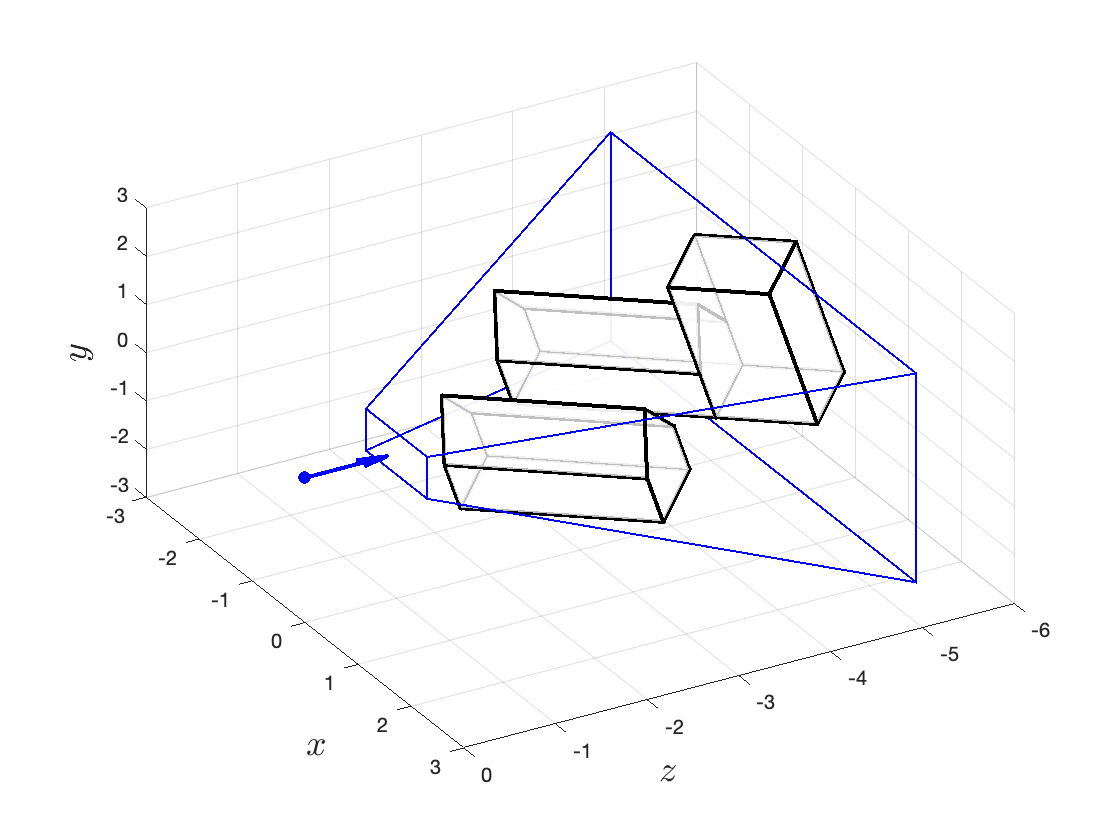

clear

% Load world space coordinates
load('camera_space_coords.mat')

% Define projection parameters
near = 1;
far = 5;
fov = pi/3;
aspect = 4/3;

% Calculate projection matrix
r = near * tan(fov / 2);
t = r / aspect;
P = [ -near / r, 0, 0, 0 ;
      0, -near / t, 0, 0 ;
      0, 0, (near + far) / (near - far), 2 * near * far / (near - far) ;
      0, 0, 1, 0 ];

% Calculate screen space co-ordinates
Vscreen = P * Vcamera;
Vscreen = Vscreen ./ Vscreen(4,:);

% Define unit cube (for the edges of the screen space)
Vcube = [ -1,  1,  1, -1, -1,  1,  1, -1 ; 
          -1, -1,  1,  1, -1, -1,  1,  1 ; 
          -1, -1, -1, -1,  1,  1,  1,  1 ];
Fcube = [ 4, 3, 2, 1 ; 
          1, 2, 6, 5 ; 
          2, 3, 7, 6 ; 
          3, 4, 8, 7 ; 
          1, 5, 8, 4 ; 
          5, 6, 7, 8 ];

% Calculate viewing frustum 
rfar = far * tan(fov / 2);
tfar = rfar / aspect;
Vfrustum = [-r, r, rfar, -rfar, -r, r, rfar, -rfar ;
    -near, -near, -far, -far, -near, -near, -far, -far ;
    -t, -t, -tfar, -tfar, t, t, tfar, tfar ];

% Plot camera space with viewing frustum
figure()
h1 = axes;
patch('Vertices', Vcamera([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=2)
patch('Vertices', Vfrustum', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue", LineWidth=1)
hold on
plot3(0,0,0,'bo',MarkerFaceColor='b')
quiver3(0,0,0,0,-1,0, 'b', LineWidth=2, MaxHeadSize=1)
hold off

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(60,45)
grid on

exportgraphics(gcf,'../images/screen_space_example_1.png','Resolution',300) 

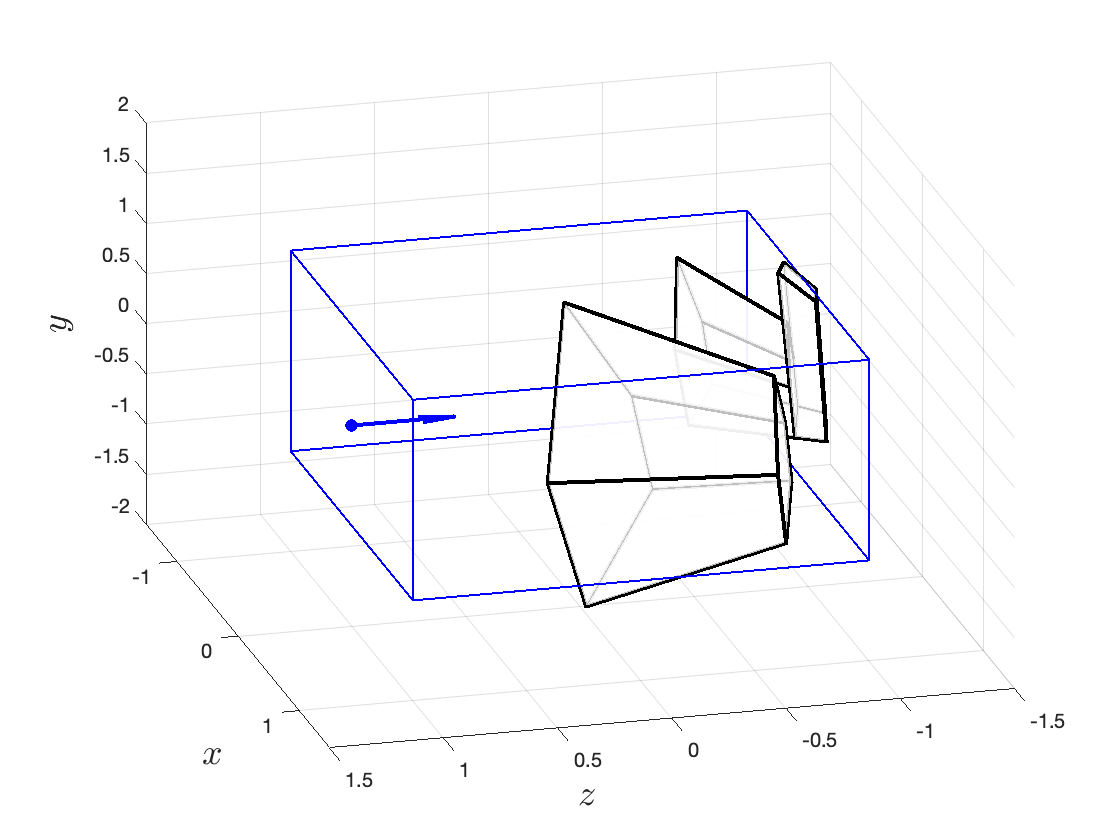

% Plot screen space viewed from the side
figure()
h1 = axes;
patch('Vertices', Vscreen([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=2)
patch('Vertices', Vcube', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue", LineWidth=1)
hold on
plot3(0,1,0,'bo',MarkerFaceColor='b')
quiver3(0,1,0,0,-0.5,0, 'b', LineWidth=2, MaxHeadSize=1)
hold off

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(75,30)
axis([-1.5, 1.5, -1.5, 1.5, -2, 2])
grid on


exportgraphics(gcf,'../images/screen_space_example_2.png','Resolution',300) 

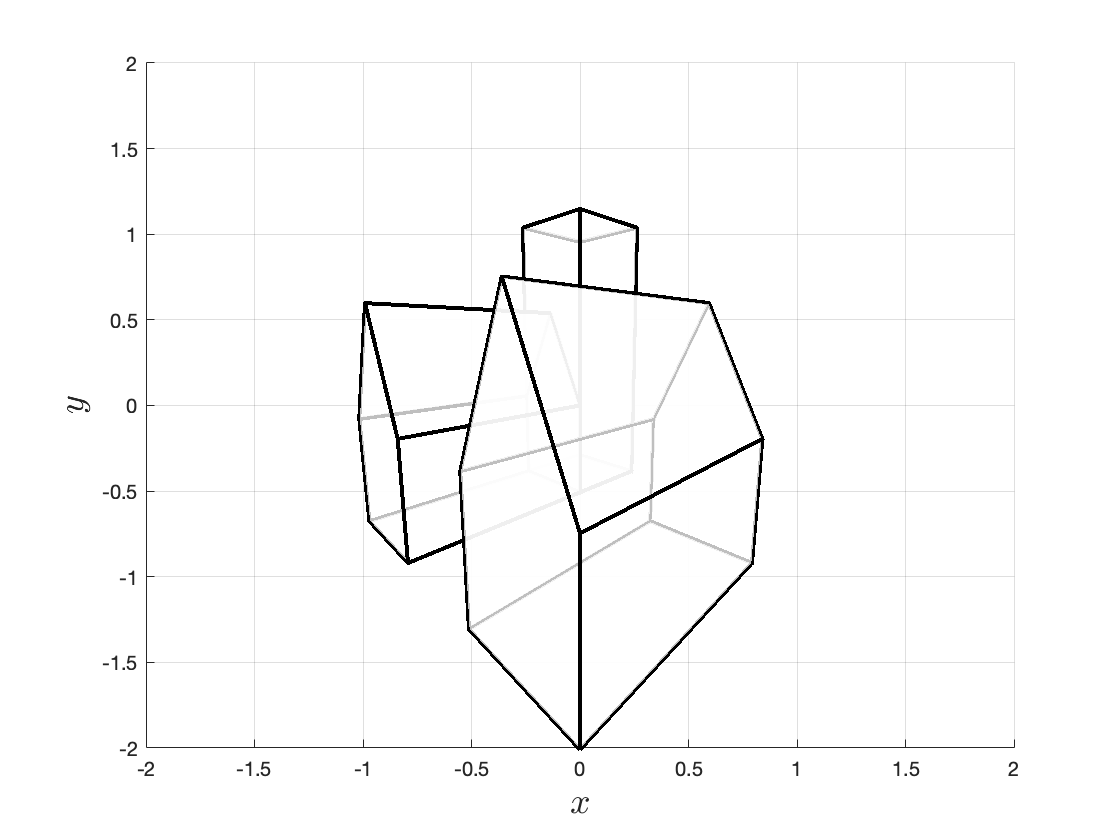


% Plot screen space viewed looking down the z-axis
figure()
h1 = axes;
patch('Vertices', Vscreen([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=2)
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(0,0)
axis([-2, 2, -2, 2, -2, 2])
grid on

exportgraphics(gcf,'../images/screen_space_example_3.png','Resolution',300)